% Stock Market Prediction Using Neural Networks
% Includes preprocessing, training, testing, and visualization.

% Step 0: Clear Environment
close all;  % Close all figures
clear;      % Clear workspace
clc;        % Clear command window
warning('off', 'MATLAB:nnet:obsolete'); % Suppress obsolete function warnings

%% Step 1: Load and Preprocess Training Data
disp('Step 1: Loading and Preprocessing Training Data...');

Step 1: Loading and Preprocessing Training Data...


fileID = fopen('stock_market_train.csv');
fgetl(fileID); % Skip header line
C = textscan(fileID, '%s %f %f %f %f', 'delimiter', ',');
fclose(fileID);

% Extract stock values
Open = cell2mat(C(1, 2)).'; % Open prices
High = cell2mat(C(1, 3)).'; % High prices
Low = cell2mat(C(1, 4)).'; % Low prices
Close = cell2mat(C(1, 5)).'; % Closing prices

% Normalize data (important for neural networks)
Open = normalize(Open, 'range');
High = normalize(High, 'range');
Low = normalize(Low, 'range');
Close = normalize(Close, 'range');

% Compute Moving Averages
disp('Calculating Moving Averages...');

Calculating Moving Averages...


SMA_10 = movmean(Open, 10); % Simple moving average
EMA_10 = movmean(Open, [9, 0]); % Exponential moving average

% Combine input features
Input = [Open; High; Low; SMA_10; EMA_10];

%% Step 2: Construct and Train Neural Network
disp('Step 2: Constructing and Training Neural Network...');

Step 2: Constructing and Training Neural Network...


hiddenLayerSize = 10; % Number of hidden neurons
net = feedforwardnet(hiddenLayerSize, 'traingdx'); % Use gradient descent with momentum

% Configure training parameters
net.trainParam.epochs = 500;         % Number of epochs
net.trainParam.goal = 1e-5;          % Tolerance for training
net.trainParam.lr = 0.01;            % Learning rate
net.divideFcn = 'dividerand';        % Randomly divide data into training/testing

% Train the network
try
    [net, tr] = train(net, Input, Close); % Train the network
catch ME
    warning('Training GUI encountered an issue: %s', ME.message);
end

% Visualize training performance
disp('Training complete. Visualizing performance...');

Training complete. Visualizing performance...


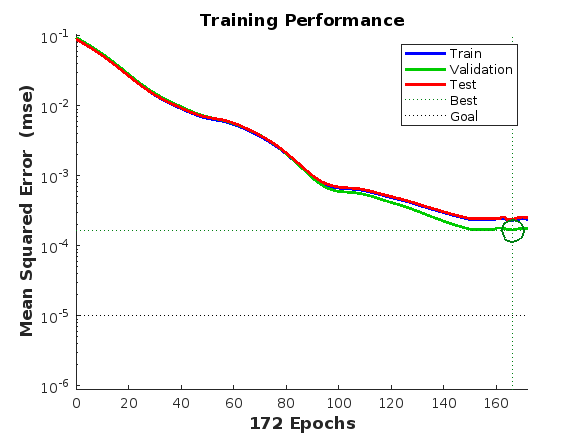

figure('Name', 'Training Performance');
plotperform(tr);
title('Training Performance');


%% Step 3: Visualize Training Results
disp('Step 3: Visualizing Training Results...');

Step 3: Visualizing Training Results...


predictedTrain = net(Input);
mseTrain = perform(net, Close, predictedTrain);
disp(['Mean Squared Error (Training): ', num2str(mseTrain)]);

Mean Squared Error (Training): 0.00022335


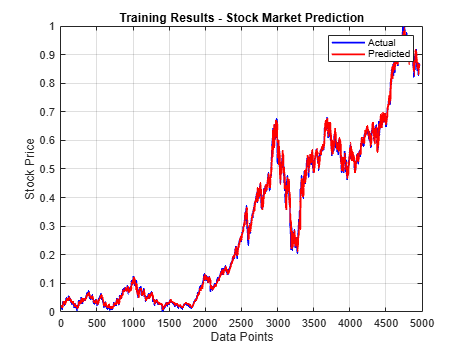


figure('Name', 'Training Results');
plot(Close, '-b', 'LineWidth', 1.5); hold on;
plot(predictedTrain, '-r', 'LineWidth', 1.5);
legend('Actual', 'Predicted');
xlabel('Data Points');
ylabel('Stock Price');
title('Training Results - Stock Market Prediction');
grid on;


%% Step 4: Load and Preprocess Testing Data
disp('Step 4: Loading and Preprocessing Testing Data...');

Step 4: Loading and Preprocessing Testing Data...


fileID = fopen('stock_market_test_final.csv');
fgetl(fileID); % Skip header line
C_t = textscan(fileID, '%s %f %f %f %f', 'delimiter', ',');
fclose(fileID);

% Extract stock values
Open_t = cell2mat(C_t(1, 2)).'; % Open prices
High_t = cell2mat(C_t(1, 3)).'; % High prices
Low_t = cell2mat(C_t(1, 4)).'; % Low prices
Close_t = cell2mat(C_t(1, 5)).'; % Closing prices

% Normalize testing data
Open_t = normalize(Open_t, 'range');
High_t = normalize(High_t, 'range');
Low_t = normalize(Low_t, 'range');
Close_t = normalize(Close_t, 'range');

% Compute Moving Averages for testing
SMA_10_t = movmean(Open_t, 10);
EMA_10_t = movmean(Open_t, [9, 0]);

% Combine input features for testing
Input_t = [Open_t; High_t; Low_t; SMA_10_t; EMA_10_t];

%% Step 5: Predict and Visualize Testing Results
disp('Step 5: Predicting and Visualizing Testing Results...');

Step 5: Predicting and Visualizing Testing Results...


predictedTest = net(Input_t);
mseTest = perform(net, Close_t, predictedTest);
disp(['Mean Squared Error (Testing): ', num2str(mseTest)]);

Mean Squared Error (Testing): 0.0024826


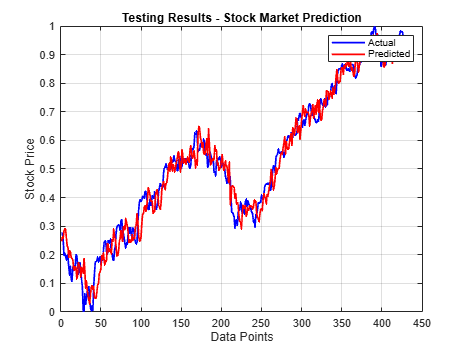


% Testing Results Visualization
figure('Name', 'Testing Results');
plot(Close_t, '-b', 'LineWidth', 1.5); hold on;
plot(predictedTest, '-r', 'LineWidth', 1.5);
legend('Actual', 'Predicted');
xlabel('Data Points');
ylabel('Stock Price');
title('Testing Results - Stock Market Prediction');
grid on;

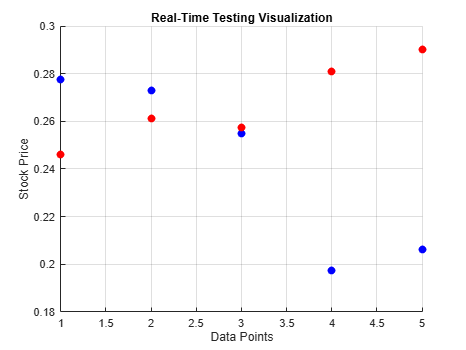


% Real-Time Testing Visualization
figure('Name', 'Real-Time Testing');
hold on;
title('Real-Time Testing Visualization');
xlabel('Data Points');
ylabel('Stock Price');
grid on;

for i = 1:length(Close_t)
    scatter(i, Close_t(i), 50, 'b', 'filled'); % Actual value
    scatter(i, predictedTest(i), 50, 'r', 'filled'); % Predicted value
    if mod(i, 5) == 0 % Update every 5 points for smooth animation
        drawnow;
    end
end

legend('Actual', 'Predicted');

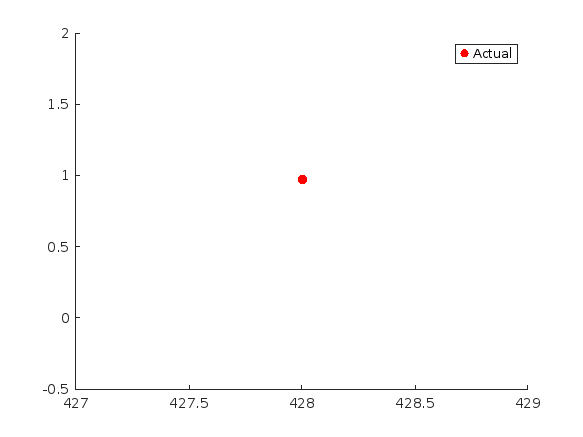

hold off;


%% Step 6: Display Final Results
disp('Step 6: Analyzing and Displaying Final Results...');

Step 6: Analyzing and Displaying Final Results...


resultsTable = table(Close_t', predictedTest', ...
    'VariableNames', {'Actual Price', 'Predicted Price'});
disp('Comparison of Actual vs Predicted Values:');

Comparison of Actual vs Predicted Values:


disp(resultsTable);

    Actual Price    Predicted Price
    ____________    _______________

       0.27761           0.2462    
       0.27314          0.26142    
       0.25506          0.25743    
       0.19744          0.28121    
       0.20601          0.29025    
       0.19465          0.28996    
       0.17979          0.25723    
       0.19767          0.23097    
       0.18924          0.22427    
        0.1562          0.19044    
       0.12849          0.21343    
       0.15878          0.21008    
       0.11537          0.18836    
       0.10499          0.18565    
       0.15419          0.18361    
       0.15942          0.14861    
       0.16009           0.1439    
       0.15771          0.15697    
        0.1994          0.15432    
       0.19463          0.11463    
       0.16493          0.12655    
       0.13213          0.17208    
       0.14409          0.16243    
       0.17303          0.15591